**Example 2-1 Linear Fitting **

**Data Generation**

close all; clear all

m=11

m = 11

x=rand(m,1);
a_true=0.3;
b_true = 0.1;
theta_true=[a_true;b_true];
noise=0.31;
y=a_true*x + b_true + noise*randn(m,1);
figure(1)
scatter(x,y)
hold on

 **Linear regression**

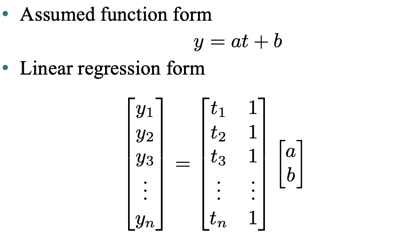

% Make regressor matrix
for i = 1: m
Regressor(i,:) = [x(i) 1];
end


**Least-square solution **

% Least-square Solution

theta_hat = (Regressor'*Regressor)\Regressor'*y

theta_hat =    -0.1777
    0.3150



y_hat = theta_hat(1)*x + theta_hat(2);


**Figure plotting **

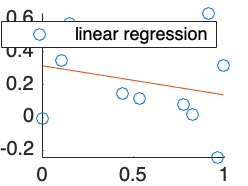

plot(x,y_hat)
legend('linear regression')

error = sqrt((theta_hat-theta_true)'*(theta_hat-theta_true))

error = 0.5238